# Signals #2: different signals, signal mixtures and signal features

## Signal diversity - adds and mults of sines, damped sines, amplitude modulation

Deterministic signals are generated from concrete mathematical recipes/prescriptions which specifies their shapes/*signatures*/*waveforms*, i.e. using mathematical functions, e.g. sin(), cos(), exp(),...:


$$x_1(t)=A\sin(2\pi f_1 t+\varphi), \qquad x_2(t)=e^{-\alpha t},  \qquad x_3(t)=e^{-\alpha (t-t_0)^2},$$


 Simple signals can add to themselves (as additive signal components) and multiply by themselves (as multiplicative  components):


$$x_4(t)=x_1(t)+x_2(t), \qquad x_5(t)=x_1(t)x_2(t) $$


. Very good example of a multiplicative signal is a damped sinusoid, i.e. a sinusoid multiplied by an exponent  - it is a solution of second order differential equations, describing damped mechanical and electrical oscillators. Let's note that sinusoid alone is a solution of differential equation describing undamped oscillators.

**Analyze the Matlab code**. Run the below section. Let the signal `x` be a different mixture of simpler components: add and  multiply them. When two signals are multiplied, each of them can be treated as a changing amplitude of the second one, i.e. modulete it in amplitude (**AM - amplitude modulation**). Damped sinusoid is the simplest example: exponent is a changing amplitude of a sine. 

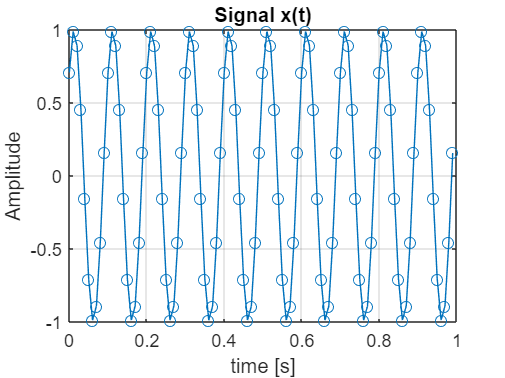

fs=100; Nx=100;              % sampling frequency, number of samples
dt = 1/fs;                   % sampling period 
t = dt*(0:Nx-1);             % sampling times (many moments)
x1=sin(2*pi*10*t+pi/4);      % sine 10 Hz as a first signal component
x2=sin(2*pi*1*t);            % sine 1 Hz
x3=exp(-5*t);                % exponent decaying in time 
x4=exp(-25*(t-0.5).^2);      % Gaussian hat
x = x1;                      % our choice: x1,...,x4, 0.23*x1 + x2, x1.*x3, x1.*x4,... 
plot(t,x,'o-'); grid; title('Signal x(t)'); xlabel('time [s]'); ylabel('Amplitude');

## Instantaneous frequency and frequency modulation

**Instantaneous frequency** of a sinusoidal signal:

 
$$x(t)=\sin(\alpha(t))$$


is defined as derivative of the signal angle $\alpha(t)$, changing in time, divided additionally by $2\pi$:


$$f_{inst}(t) = \frac{1}{2\pi} \frac{\text{d}\alpha (t)}{\text{d}t} $$


For this reason, in order to obtain a sinusoidal signal having required instantaneous frequency $f_{inst}(t)$, it is necesary to set:


$$\alpha(t) = 2 \pi \int_{0}^{t} f_{inst}(t) dt.$$


In Matlab:

`alpha = 2*pi*cumsum( finst )*dt`.

Now we will test this.

**Analyze the Matlab code**.  Change modulation parameters. Add amplitude modulation.

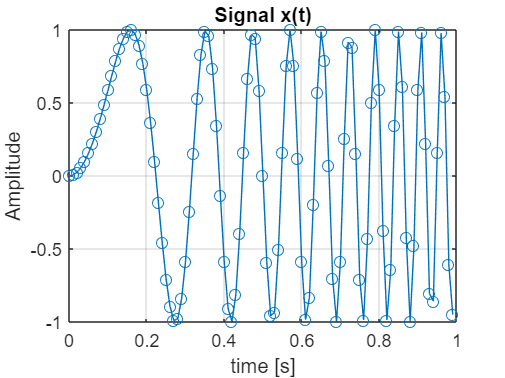

x5=sin(2*pi*(0*t+0.5*20*t.^2));                 % linear freq. increase: start 0 Hz, +20Hz/s
x6=sin(2*pi*(10*t-(9/(2*pi*1)*cos(2*pi*1*t)))); % sinus. FM: 9Hz around 10Hz, 1 per sec
x7=sin(2*pi*(10*t+9*cumsum(x2)*dt));            % the same as x6; why?
x = x5;                                         % our choice: x5,x6,7 
plot(t,x,'o-'); grid; title('Signal x(t)'); xlabel('time [s]'); ylabel('Amplitude');

**Analyze the Matlab code**. Finally, we will generate an FM modulated alarm signal for a fire truck. Enlarge the signal plot and observe the signal shape. Check correctness of frequency change in the spectrogram plot. Modify values of signal parameters.

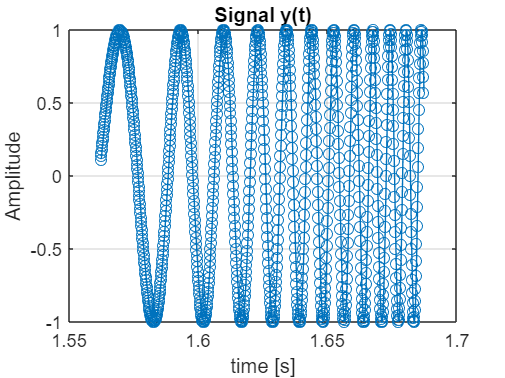

fs=8000; Nx=8*fs;                    % sampling frequency, number of samples
dt = 1/fs; t = dt*(0:Nx-1);          % sampling period, sampling times (many moments)
y1=sin(2*pi*(0*t+0.5*1000*t.^2));    % linear frequency increase: start 0 Hz, +1000Hz/s
y2=sin(2*pi*(1000*t-(990/(2*pi*0.5)*cos(2*pi*0.5*t))));  % sinusoidal FM
y3=sin(2*pi*(1000*t+990*cumsum(cos(2*pi*0.5*t))*dt));    % the same as x6; why?
y = y2;                                                  % our choice: y1,y2,y3  
sound(0.1*y,fs);                                         % listening 
figure; plot(t,y,'o-'); grid; title('Signal y(t)'); xlabel('time [s]'); ylabel('Amplitude');

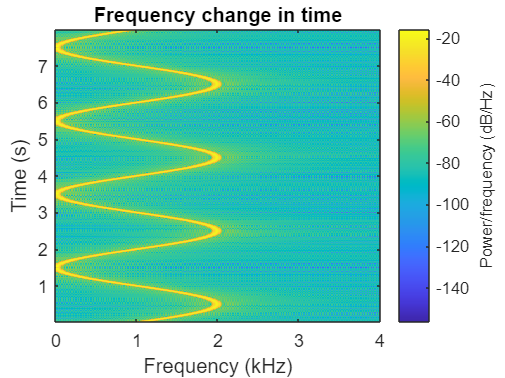

figure; spectrogram(y,256,256-32,512,fs); title('Frequency change in time');

## Signal features

Any signal has the following features/descriptors: min / max / peak-to-peak / mean value, variance, standard deviation, energy, power, rms value, auto-correlation function. Find their definitions and calculate them for our signals. Find and test Matlab functions computing signal feattures (e.g. `min, max, var, std, rms, xcorr`). 